Initialise an MSE_values matrix that will store the experimental data.

MSE_values = [];

Then iterate through the multireservoir script for however many variations of numbers of reservoirs *n* you want, 100 times each and store the results in the MSE_values matrix.

for n = [1,2,4,5,10,20,25,50,100]
    for k = 1:10
        
        trainLen = 2000;
        testLen = 2000;
        data = load('MackeyGlass_t17.txt');

        a = 0.8;
        s = 0.01;
        rand( 'seed', k );

        numberOfReservoirs = n;
        resSize = fix(100 / numberOfReservoirs);
        inSize = 1;

        [Win, W] = deal(cell(1,numberOfReservoirs));
        for i = 1:numberOfReservoirs
            Win{i} = (rand(resSize,1+inSize)-0.5) .* 1;
            W{i} = rand(resSize,resSize)-0.5;

            rhoW = abs(eigs(W{i},1,'LM'));
            W{i} = W{i} .* ( 1.25 /rhoW);

            for j = 1:numel(W{i})
                if rand > s
                    W{i}(j) = 0;
                end
            end
            for j = 1:numel(Win{i})
                if rand > s
                    Win{i}(j) = 0;
                end
            end
        end

        resSizeMini = 20;

        inSizeMini = resSize*numberOfReservoirs; outSizeMini = 1;

        WinMini = (rand(resSizeMini,1+inSizeMini)-0.5) .* 1;
        WMini = rand(resSizeMini,resSizeMini)-0.5;
        rhoW = abs(eigs(WMini,1,'LM'));
        WMini = WMini .* ( 1.25 /rhoW);

        for j = 1:numel(WMini)
            if rand > s
                WMini(j) = 0;
            end
        end
        for j = 1:numel(WinMini)
            if rand > s
                WinMini(j) = 0;
            end
        end

        X = zeros(1+numberOfReservoirs*(inSize+resSize)+resSizeMini);

        Yt = data(2:trainLen+1)';

        x = cell(1,numberOfReservoirs);
        for i = 1:numberOfReservoirs
            x{i} = zeros(resSize,1);
        end

        xMini = zeros(resSizeMini,1);

        for t = 1:trainLen    
            u = data(t);   
            for i = 1:numberOfReservoirs
                if ~rem(t,i)
                    x{i} = (1-a)*x{i} + a*tanh( Win{i}*[1;u] + W{i}*x{i} );
                end
            end

            xMini = (1-a)*xMini + a*tanh( WinMini*[1;cell2mat(x')] + WMini*xMini ); 

            X(:,t) = [1;repmat(u,1,numberOfReservoirs)';cell2mat(x');xMini];
        end

        reg = 1e-8;
        Wout = Yt*X' * inv(X*X' + reg*eye(1+numberOfReservoirs*(inSize+resSize)+resSizeMini));

        Y = zeros(outSizeMini,testLen);
        u = data(trainLen+1);
        for t = 1:testLen 

            for i = 1:numberOfReservoirs
                if ~rem(t,i)
                    x{i} = (1-a)*x{i} + a*tanh( Win{i}*[1;u] + W{i}*x{i} );
                end
            end

            xMini = (1-a)*xMini + a*tanh( WinMini*[1;cell2mat(x')] + WMini*xMini );

            y = Wout*[1;repmat(u,1,numberOfReservoirs)';cell2mat(x');xMini];
            Y(:,t) = y;

            u = data(trainLen+t+1);
        end

        errorLen = 500;
        desired_output = data(trainLen+2:trainLen+errorLen+1)';
        system_output = Y(1,1:errorLen);
        mse = sum((desired_output-system_output).^2)./errorLen;
        nmse = mean((desired_output - system_output).^2)/var(desired_output);
        disp( ['MSE = ', num2str( mse ),' NMSE = ', num2str( nmse )] );
        
        MSE_values(n, k) = mse;
    end
end

MSE = 1.2063e-05 NMSE = 0.00025575
MSE = 7.7343e-06 NMSE = 0.00016398
MSE = 1.0769e-05 NMSE = 0.00022833
MSE = 9.3474e-06 NMSE = 0.00019818
MSE = 0.0010212 NMSE = 0.021651
MSE = 1.1901e-05 NMSE = 0.00025233
MSE = 0.0010214 NMSE = 0.021656
MSE = 7.9253e-06 NMSE = 0.00016803
MSE = 1.2014e-05 NMSE = 0.00025472
MSE = 4.9832e-05 NMSE = 0.0010565
MSE = 2.3723e-05 NMSE = 0.00050296
MSE = 0.00026328 NMSE = 0.0055819
MSE = 2.6718e-05 NMSE = 0.00056646
MSE = 0.0010214 NMSE = 0.021656
MSE = 0.0010209 NMSE = 0.021645
MSE = 1.2822e-05 NMSE = 0.00027185
MSE = 1.1172e-05 NMSE = 0.00023687
MSE = 0.0010214 NMSE = 0.021656
MSE = 0.0010212 NMSE = 0.021651
MSE = 0.0010214 NMSE = 0.021656
MSE = 0.00029157 NMSE = 0.0061818
MSE = 0.00029104 NMSE = 0.0061706
MSE = 0.00029174 NMSE = 0.0061852
MSE = 0.0010214 NMSE = 0.021656
MSE = 0.0010212 NMSE = 0.021651
MSE = 0.00015171 NMSE = 0.0032164
MSE = 4.9578e-05 NMSE = 0.0010511
MSE = 5.7398e-05 NMSE = 0.0012169
MSE = 0.0010212 NMSE = 0.021651
MSE = 0.0010214 NMSE = 

Plot the experiment data as a boxplot.

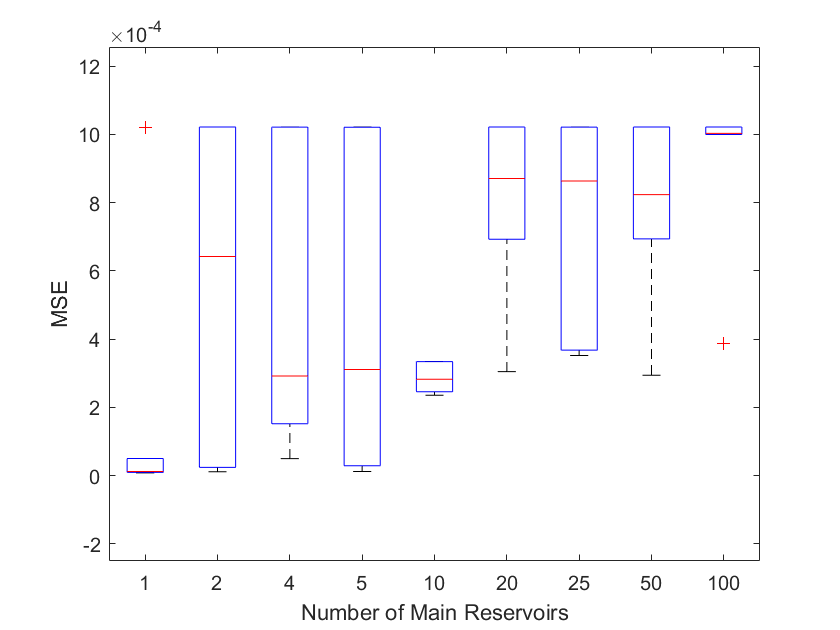

boxplot(MSE_values([1,2,4,5,10,20,25,50,100],:)', {1,2,4,5,10,20,25,50,100});
xlabel('Number of Main Reservoirs')
ylabel('MSE')